qf = @(A,b,x1,x2)  (1/2)*(A(1,1)*x1.^2 + (A(1,2) + A(2,1))*(x1.*x2)+ A(2,2)*x2.^2) - ...
    (b(1)*x1 + b(2)*x2) +(1/2)*b'*(A\b);
A=[1,0;0,2];
b=[1;2];
%c=(1/2)*b'*(A\b)
x1 = 0:0.1:2; %también se puede usar linspace
x2 = 0:0.1:2;
[X1,X2]=meshgrid(x1,x2); %maya de puntos para calcular para cada punto cuanto vale la función
f = qf(A,b,X1,X2);
minimo = min(min(f)) %valor minimo

minimo = 0

f==minimo

ans = 21×21 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


[iMin,jMin] = find(f==minimo)

iMin = 11

jMin = 11

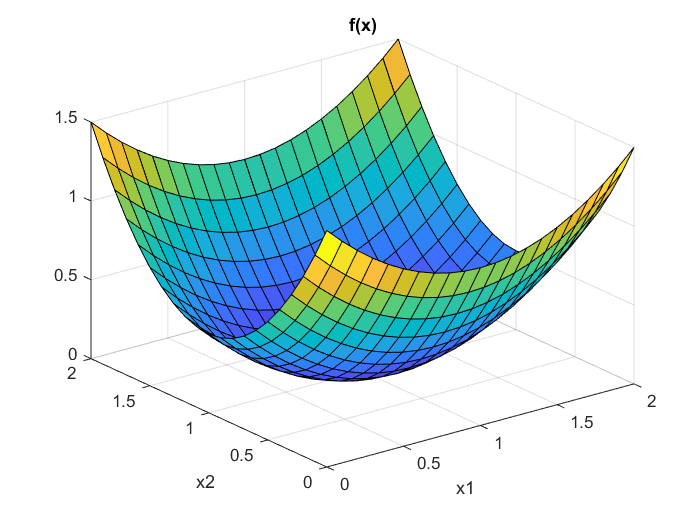

surf(X1,X2,f)
xlabel('x1');
ylabel('x2');
title('f(x)')

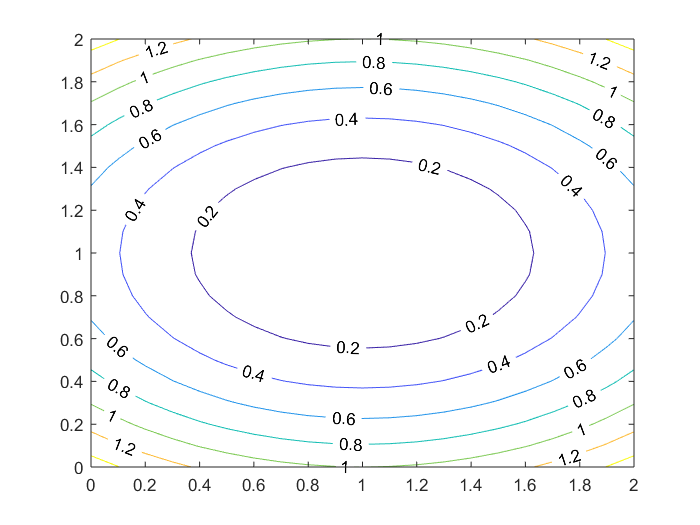


[cs,h] = contour(x1,x2,f);
clabel(cs,h)

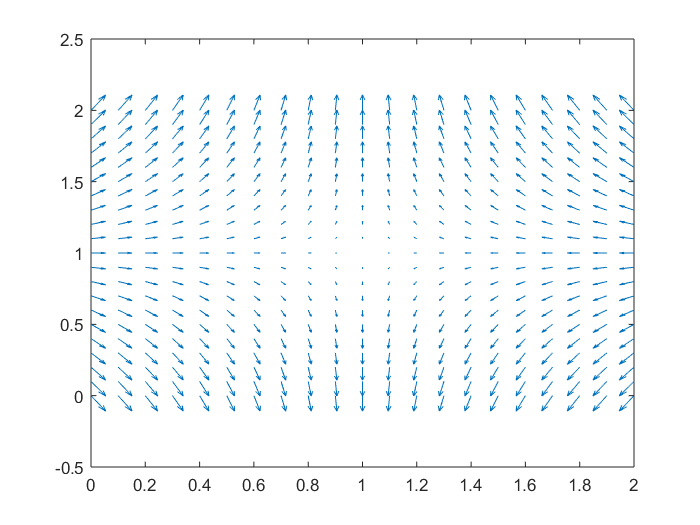

[fx1,fx2] = gradient(f,0.25); %el 0.25 es el espaciado entre las flechitas
quiver(x1,x2,-fx1, fx2) %para poner las fechitas con la dirección del menos gradiente

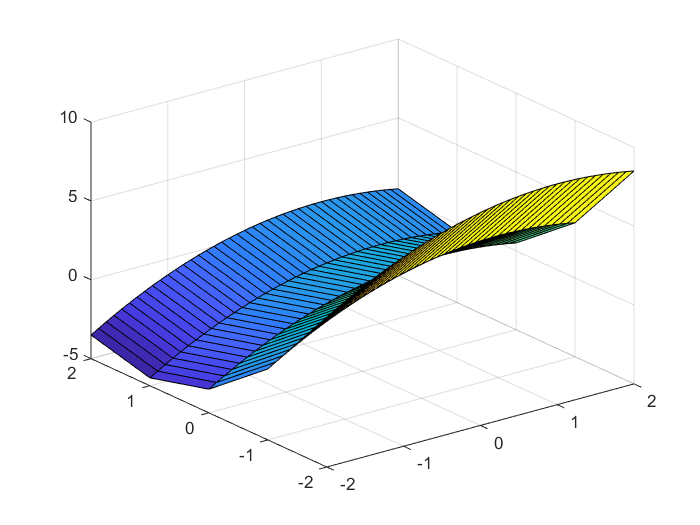

A = [-1,0;0,2];
b = [-1;2];
[X1,X2] = meshgrid(-2:0.1:2,-2:01:2);
f = qf(A,b,X1,X2);
surf(X1,X2,f)